clc
clear

## Afinador de Guitarra

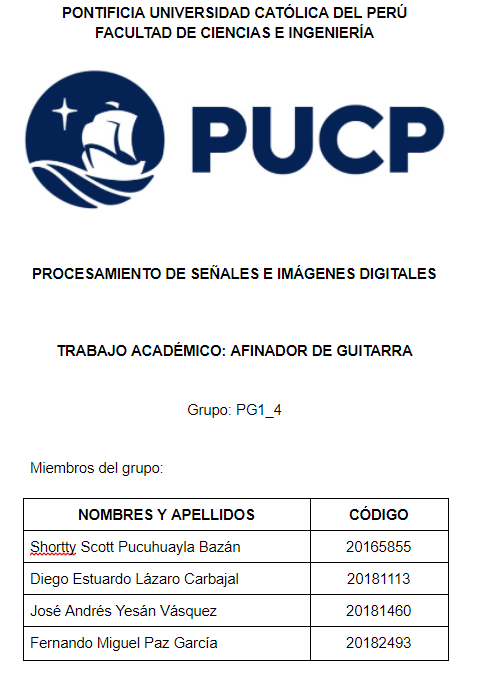

En el presente proyecto, se ha hecho uso de las diferentes herramientas enseñadas en le curso para el procesamiento de señales con el objetivo de crear un programa interactivo para la afinación de guitarras. A continuación se explicará las diferentes etapas del programa desarrollado.

Primero, el usuario que desee afinar su guitarra debe seleccionar cual cuerda es la que va a probar, para esto usamos el comando "input". Cuando coloca el número de la cuerda, a partir de esta se genera un número, el cual define el intervalo que se desea analizar. Considerando la nota la4 de 440 Hz como la posición "0", las primera cuerda de la guitarra se encontraría en la posición "-5", y la sexta en la pocision "-29". De este modo, se define la nota que se desea alcanzar.

prompt='ingrese el número de cuerda: ';
mode = input(prompt);
switch mode
    case 1
        x = -5;
    case 2
        x = -10;
    case 3
        x = -14;
    case 4
        x = -19;
    case 5
        x = -24;
    case 6
        x = -29;
end

***Detección de señal***

Luego se procede a efectuar la grabación del audio el cual contiene la nota musical que se desea afinar. Utilizaremos solo un canal para la detección de audio con un resilucion de 16 bitsy una frecuencia de muestreo de 2kHz

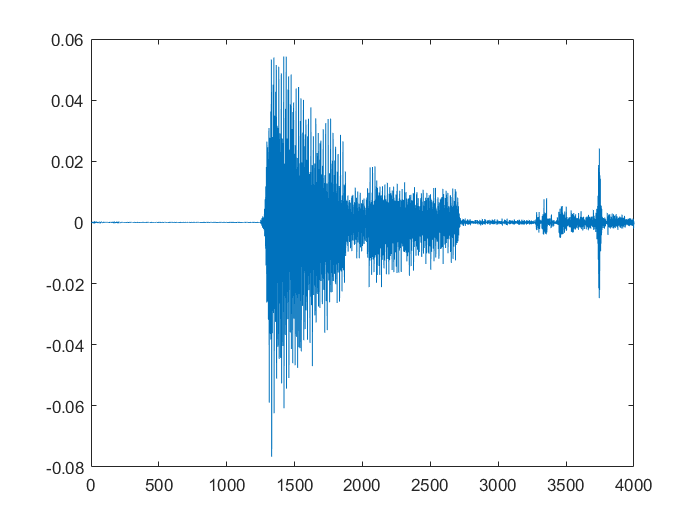

fs = 2000;
recObj = audiorecorder(fs, 16, 1);
recordblocking(recObj, 2);
y = getaudiodata(recObj);

plot(y)

***Filtrado de señal:***

Despues de tener la grabación, se realiza el filtraje de sonido, para eliminar cualquier tipo de ruido de freceuncia altas y poder realizar el análisis a solo las frecuencias bajas pertinentes. Este filtrado, el cual serpa con u filtro butterword, se realiza dependiendo de la nota que se desea afinar, ya que se utilizará un filtroo pasabanda el cual, tendrá sus parámetros en función de valores cercanos a la frecuencia esperada que se desea afinar. De esta manera, se verificará si la frecuencia de la nota detectada corresponde al valor corresponidete o si está fuera del rango permitido:

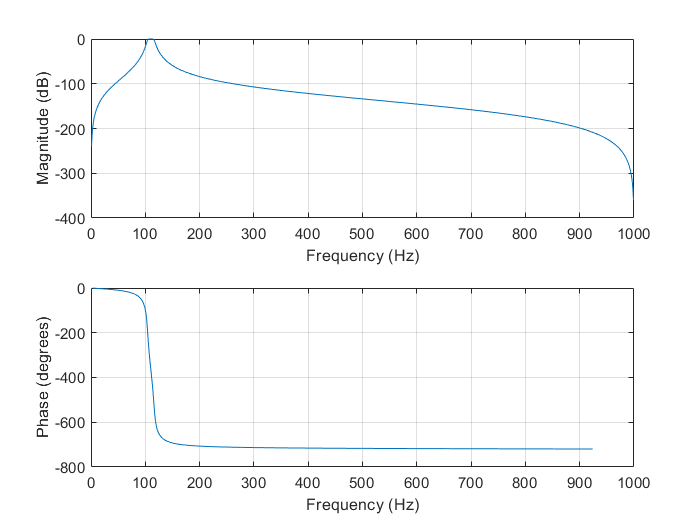

F1 = 440*2^((x-1)/12);
F2 = 440*2^((x+1)/12);
wp1 = F1/(fs/2);
wp2 = F2/(fs/2);
Wp= [wp1 wp2];

[b, a] = butter(4,Wp,'bandpass');
freqz(b,a,1024,fs)

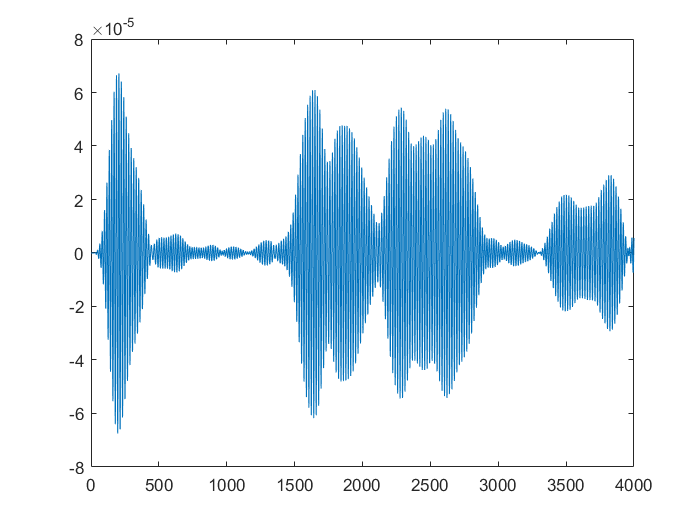


y1= filter(b,a,y);
plot(y1)

***Análisis por periodograma de Welch:***

Para el análisis de señal, se de define un solapamiento del 90% para una cantidad de datos igual al 0.5 de la frecuencia de muestreo. Asimismo, se definió la potencia  de 2 próxima a la cantidad de datos. Con esos datos definidos, se aplica el método Welch a la señal filtrada.

También, se realiza una comparación en los espectogramas entre la señal grabada con la filtrada y se concluye que, a diferencia con la señal grabada, la señal filtrada presenta no solo menos picos, sino que reduce considerablemente el ruido ambiental, debido a que, en la etapa anterior, se aplica un filtraje pasa banda.

Finalmente, se halla el pico máximo de las frecuencias pasantes y se almacena en pk

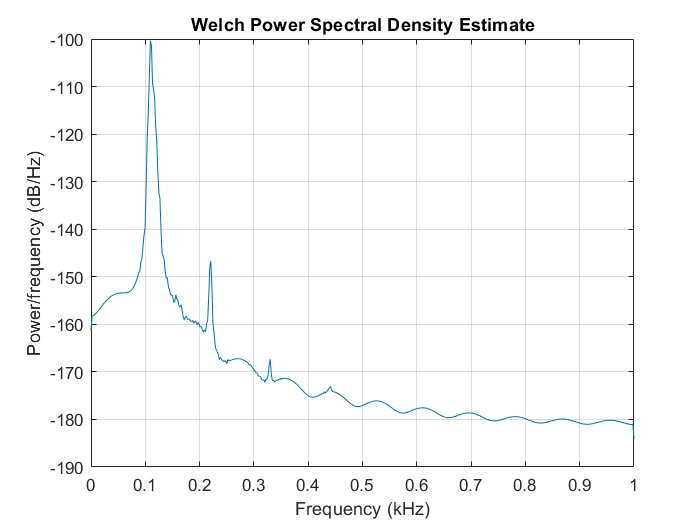

L = 0.5*fs;
overlap = floor(0.9*L);
nfft = 2^nextpow2(L);
[pxx,f] = pwelch(y1,hamming(L),overlap,nfft,fs);
figure
pwelch(y1,hamming(L),overlap,nfft,fs);

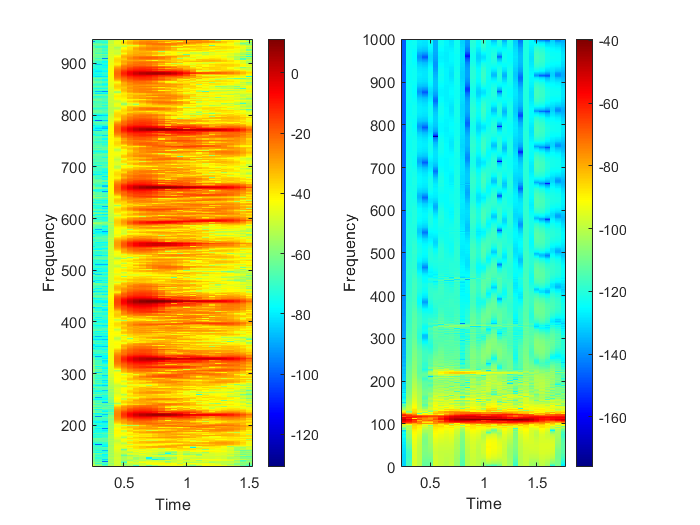

figure
subplot(1,2,1)
specgram(y,nfft,fs,hamming(L),overlap); colorbar;
subplot(1,2,2)
specgram(y1,nfft,fs,hamming(L),overlap); colorbar;


[pks, locs] = findpeaks(pxx,'SortStr','descend','NPeaks',1);
pk= f(locs);

***Respuesta al usuario:***

Luego de obtener el mayor valor de los picos de freciencias pasantes, se realiza la comparación con los valores normalizados de frecuencias correspondientes a cada nota producida por cada cuerda. Estos valores se calculan con cierta realción matemática descrita más adelante. Así, se compara el valor detecatdo de frecuencia con el valor esperado y se indica al usuario si la nota está en el ramgo permisible, si está fuera por defecto o exceso:

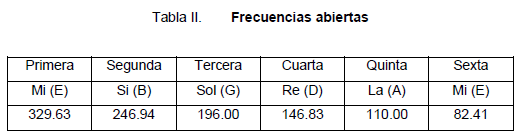

pk1 = string(pk);
disp("Frecuencia Actual: " + pk1);

Frecuencia Actual: 109.375


order = 12 * log2(pk/440);

n = x - order;
if n < - 0.35 
    disp("Estado: Por encima de la frecuencia");
elseif n > 0.35
    disp("Estado: Por debajo de la frecuencia");
else
    disp("Estado: En rango");
end

Estado: En rango
